## ! note -> run the 'Q1_part1_preprocessing.mlx' first to have the 'EEG.data' in your workspace

events = readtable('events.csv');

## 1) Find event number of *face*, *chair* and *dog*

face_events_number = events(strcmp(events.object, 'face'),'eventnumber');
dog_events_number = events(strcmp(events.object, 'dog'),'eventnumber');
chair_events_number = events(strcmp(events.object, 'chair'),'eventnumber');

## 2) creating RDMs

### *Face* events channel data

 channel_num = length(EEG.data(:,1,1));
 timeslots = 225-175+1;
 face_event_num = length(face_events_number.eventnumber);
 face_event_3D = zeros(channel_num ,timeslots ,face_event_num );
 
for i = 1:length(face_events_number.eventnumber)
    face_event_3D(:,:,i) = EEG.data(:, 175:225, face_events_number.eventnumber(i));
end

### *Dog* events channel data


 dog_event_num = length(dog_events_number.eventnumber);
 dog_event_3D = zeros(channel_num ,timeslots ,dog_event_num );
 
for i = 1:length(dog_events_number.eventnumber)
    dog_event_3D(:,:,i) = EEG.data(:, 175:225, dog_events_number.eventnumber(i));
end

### *Chair* events channel data

 chair_event_num = length(chair_events_number.eventnumber);
 chair_event_3D = zeros(channel_num ,timeslots ,chair_event_num );
 
for i = 1:length(chair_events_number.eventnumber)
    chair_event_3D(:,:,i) = EEG.data(:, 175:225, chair_events_number.eventnumber(i));
end

listmean_face = zeros(length(EEG.data(:,1,1)) , length(face_events_number.eventnumber));
for j = 1:length(EEG.data(:,1,1))
    list = zeros(length(face_events_number.eventnumber) , timeslots); 
    for i = 1:length(face_events_number.eventnumber)  
        list(i , :) = face_event_3D(j,:,i);
    end
    listR = list';
    listmean_face(j ,:) = mean(listR);
end

listmean_dog = zeros(length(EEG.data(:,1,1)) , length(dog_events_number.eventnumber));
for j = 1:length(EEG.data(:,1,1))
    list = zeros(length(dog_events_number.eventnumber) , timeslots); 
    for i = 1:length(dog_events_number.eventnumber)  
        list(i , :) = dog_event_3D(j,:,i);
    end
    listR = list';
    listmean_dog(j ,:) = mean(listR);
end

listmean_chair = zeros(length(EEG.data(:,1,1)) , length(chair_events_number.eventnumber));
for j = 1:length(EEG.data(:,1,1))
    list = zeros(length(chair_events_number.eventnumber) , timeslots); 
    for i = 1:length(chair_events_number.eventnumber)  
        list(i , :) = chair_event_3D(j,:,i);
    end
    listR = list';
    listmean_chair(j ,:) = mean(listR);
end

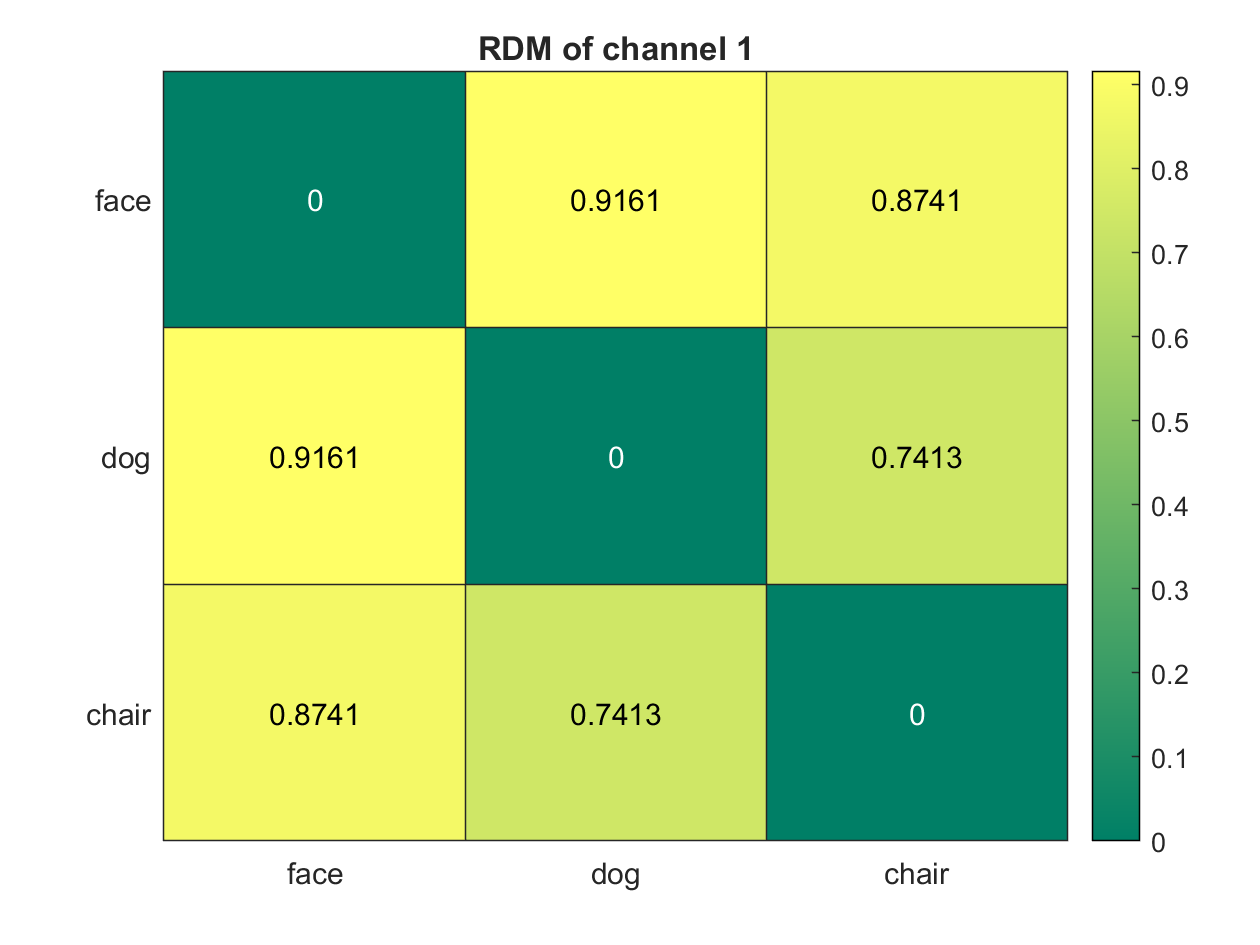

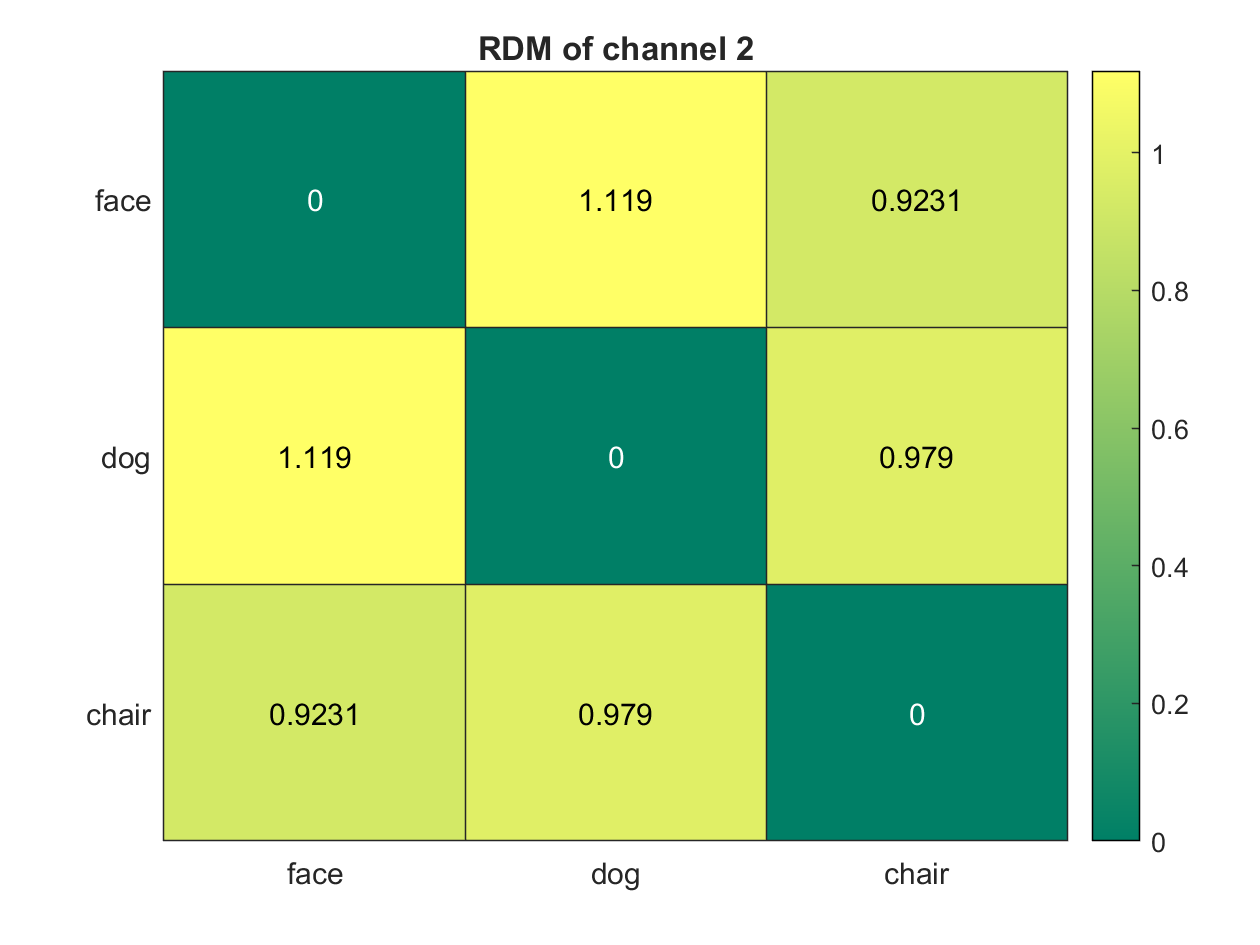

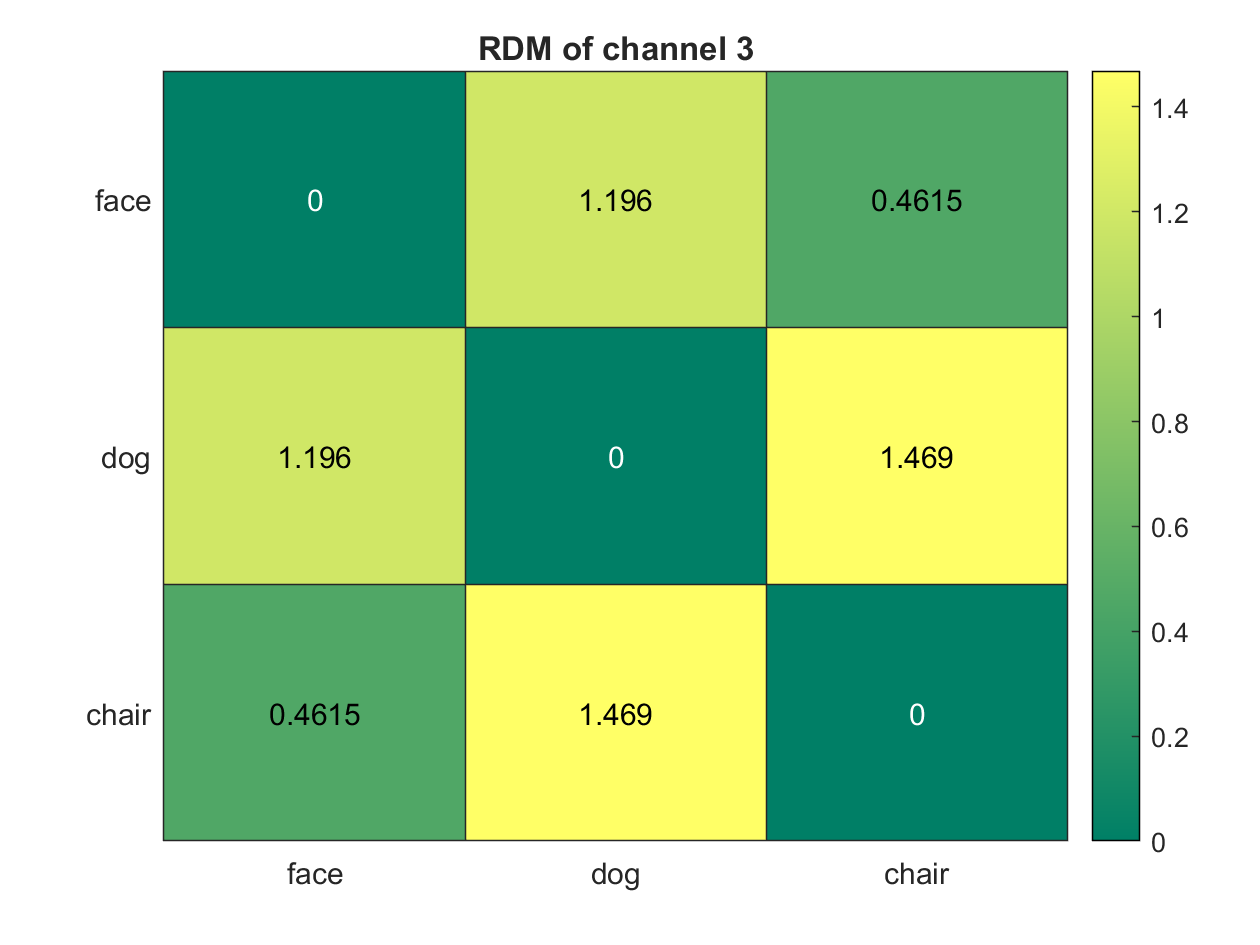

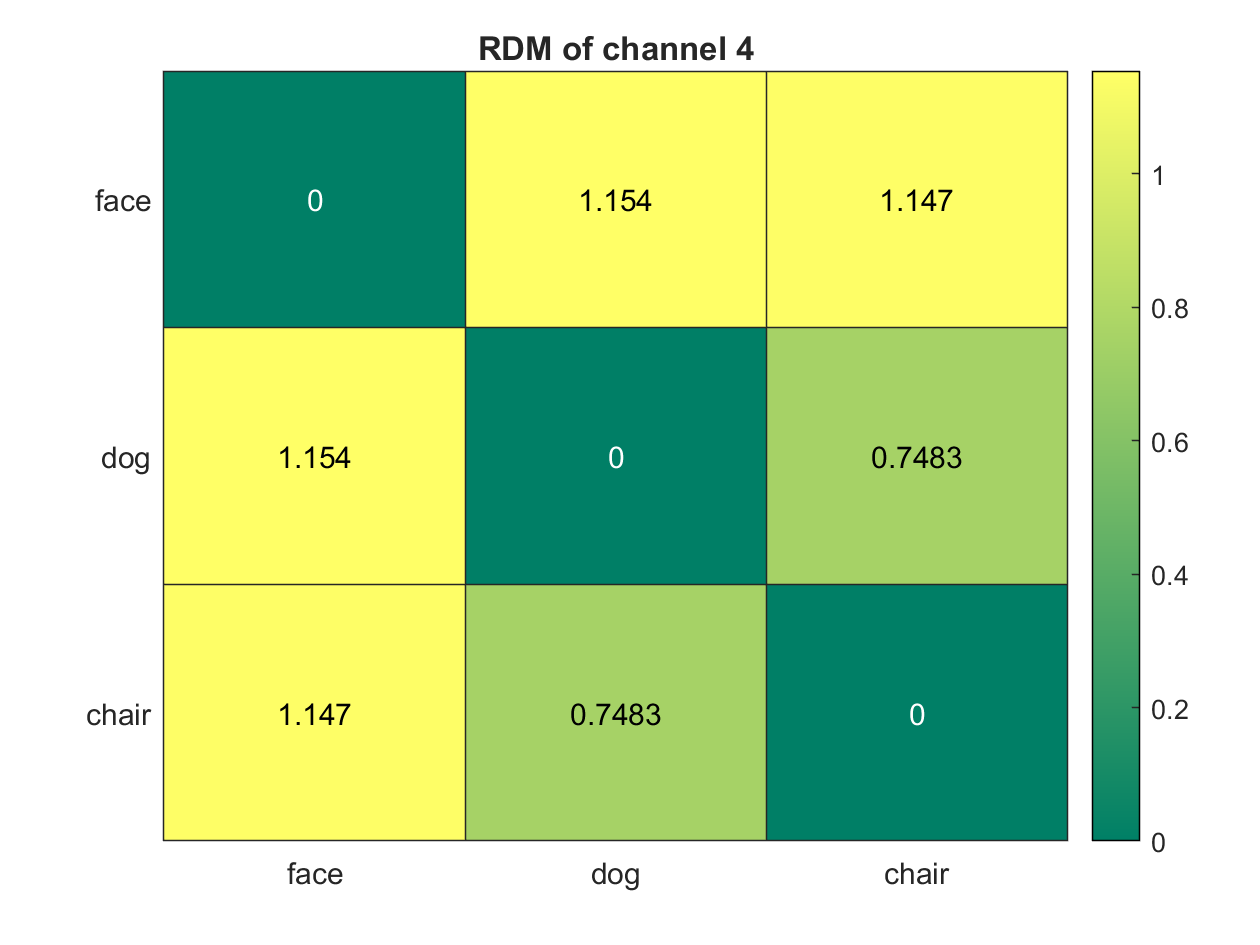

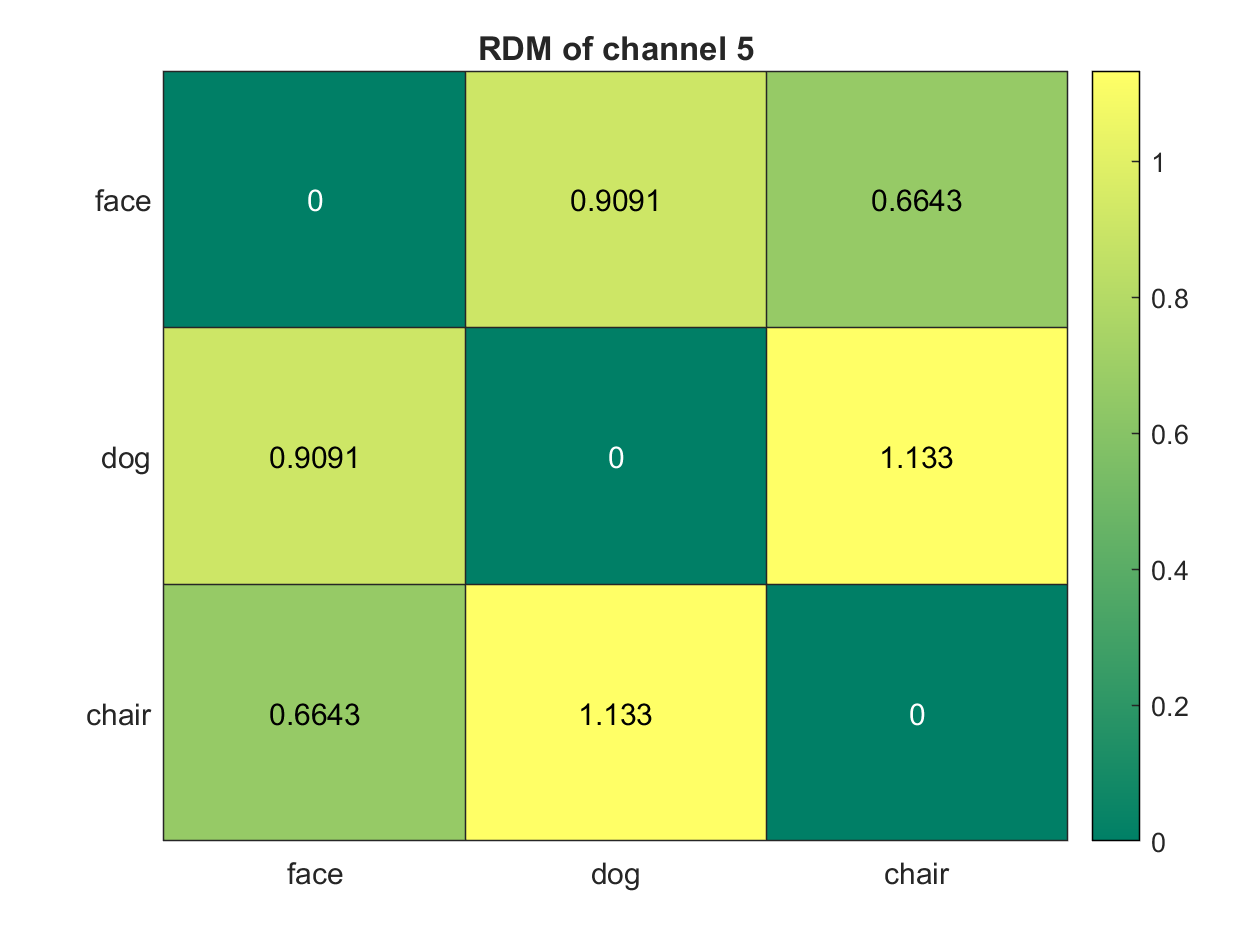

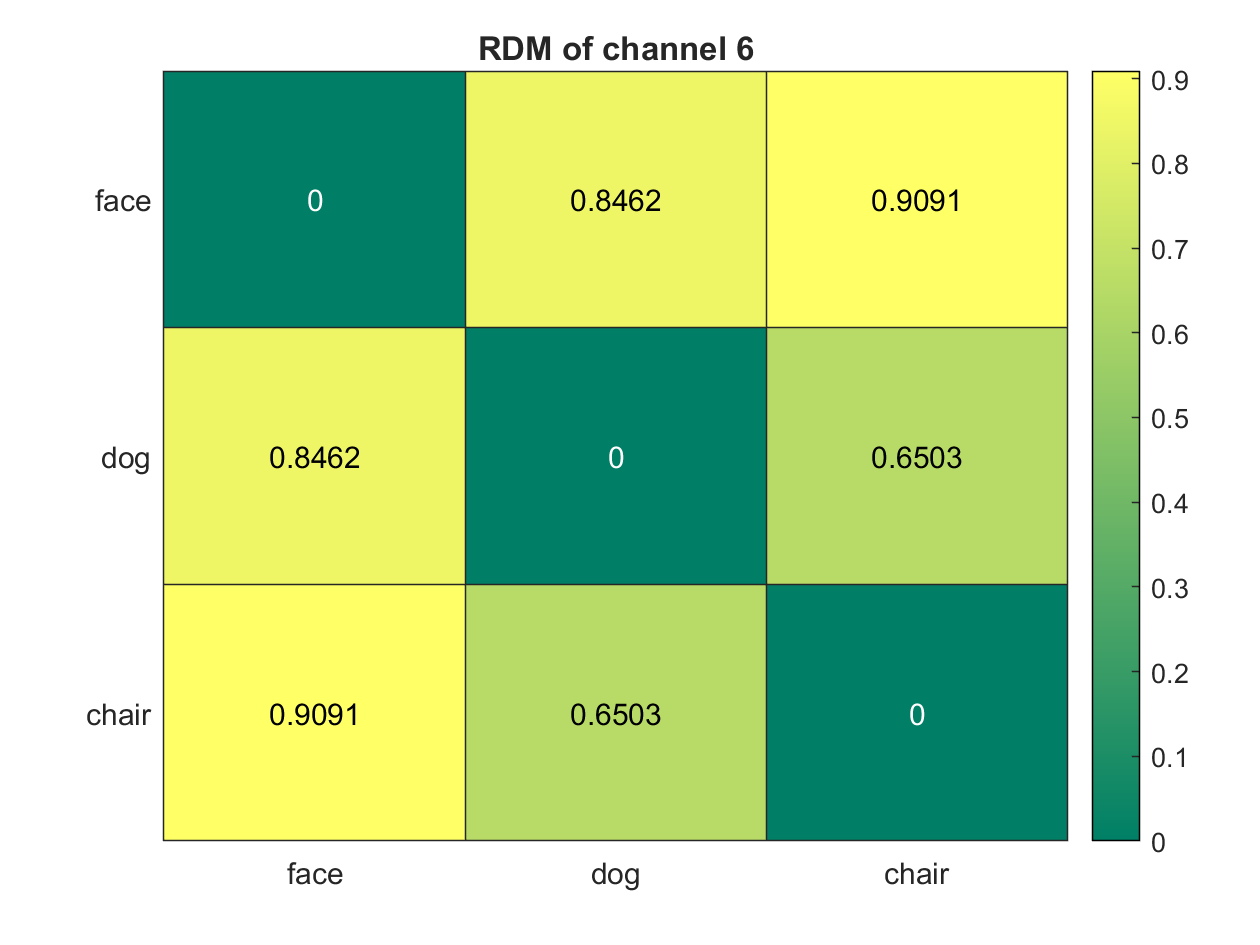

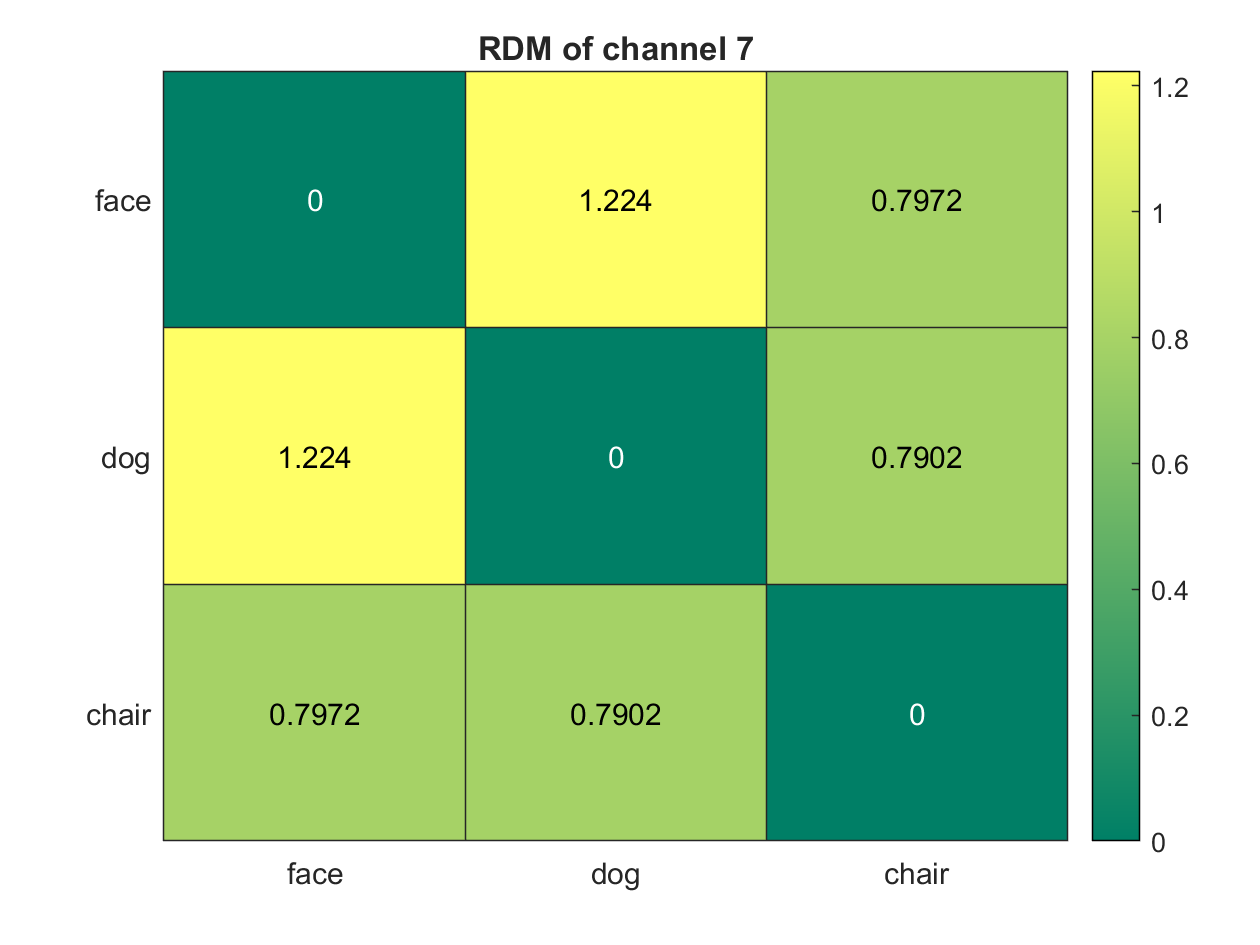

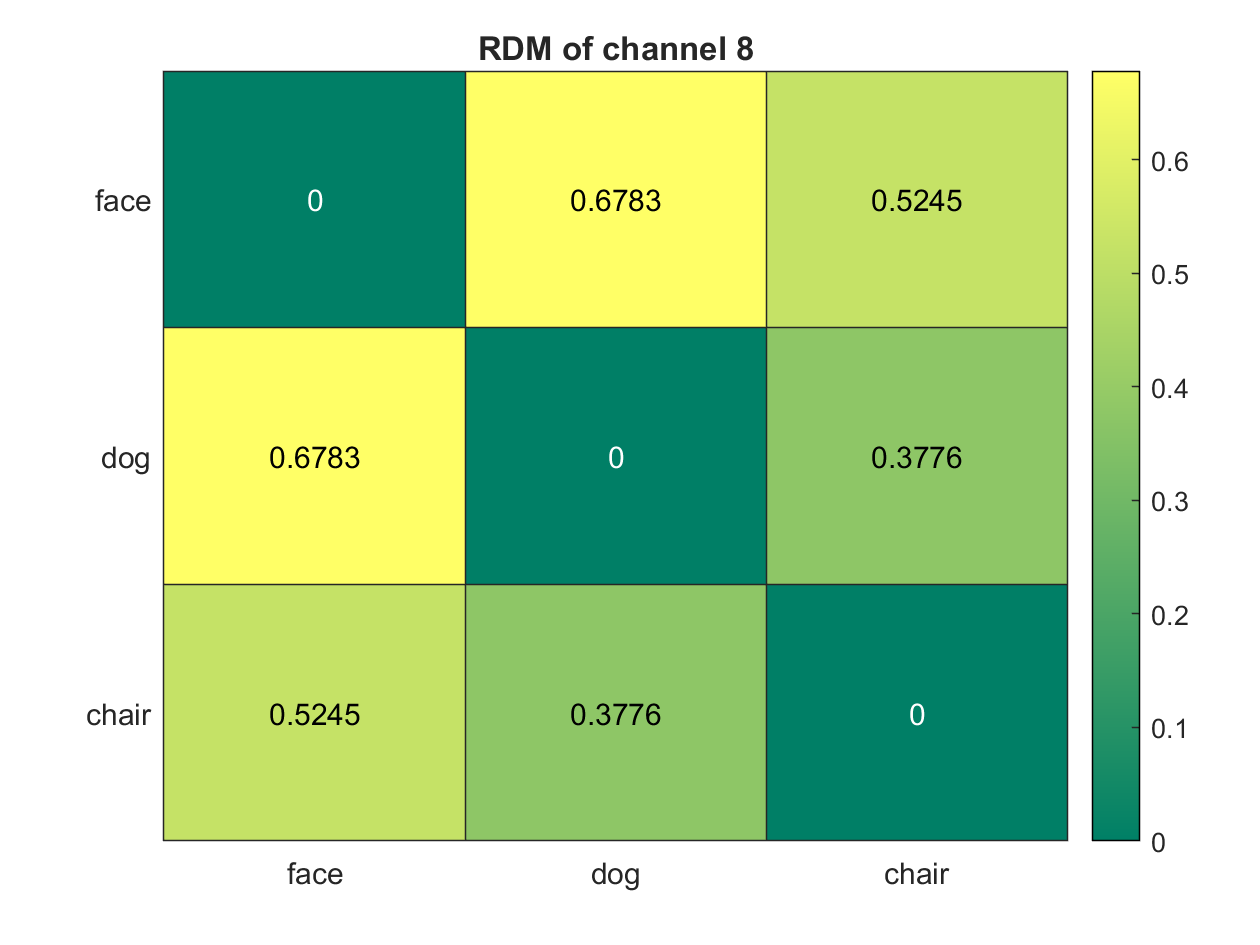

rdm = zeros(3  ,  3);

for i = 1:length(EEG.data(:,1,1))
    rdm = zeros(3  ,  3);
    [RHO,PVAL] = corr(listmean_face(i,:)',listmean_dog(i,:)','Type','Spearman');
    dsm = 1 - RHO;
    rdm(1 ,2) = dsm;
    rdm(2 ,1) = dsm;
    
    [RHO,PVAL] = corr(listmean_face(i,:)',listmean_chair(i,:)','Type','Spearman');
    dsm = 1 - RHO;
    rdm(1 ,3) = dsm;
    rdm(3 ,1) = dsm;
     
        
    [RHO,PVAL] = corr(listmean_chair(i,:)',listmean_dog(i,:)','Type','Spearman');
    dsm = 1 - RHO;
    rdm(2 ,3) = dsm;
    rdm(3 ,2) = dsm;
    figure;
    h = heatmap(rdm,'Colormap',summer);%'MissingDataColor', 'w', 'GridVisible', 'off', 'MissingDataLabel', " ")
    %h.Colormap = 
    formattitle = 'RDM of channel %d';
    h.Title = sprintf(formattitle,i);
    h.XData = {'face','dog','chair'};
    h.YData = {'face','dog','chair'};
end

## 3) RSA model of RDMs    

face_vs = zeros(1,length(face_event_3D(1,:,1)));
for i=1:length(face_event_3D(1,:,1))
    mean_face = mean(transpose(squeeze(face_event_3D(:,i,:))));
    mean_others_than_face = mean(transpose( (squeeze(chair_event_3D(:,i,:))  + squeeze(dog_event_3D(:,i,:)))/2 ));
    [RHO,PVAL] = corr(mean_face',mean_others_than_face','Type','Spearman');
    face_vs(i) = RHO;
end

dog_vs = zeros(1,length(dog_event_3D(1,:,1)));
for i=1:length(dog_event_3D(1,:,1))
    mean_dog = mean(transpose(squeeze(dog_event_3D(:,i,:))));
    mean_others_than_dog = mean(transpose( (squeeze(chair_event_3D(:,i,:))  + squeeze(face_event_3D(:,i,:)))/2 ));
    [RHO,PVAL] = corr(mean_dog',mean_others_than_dog','Type','Spearman');
    dog_vs(i) = RHO;
end

chair_vs = zeros(1,length(chair_event_3D(1,:,1)));
for i=1:length(chair_event_3D(1,:,1))
    mean_chair = mean(transpose(squeeze(chair_event_3D(:,i,:))));
    mean_others_than_chair = mean(transpose( (squeeze(dog_event_3D(:,i,:))  + squeeze(face_event_3D(:,i,:)))/2 ));
    [RHO,PVAL] = corr(mean_chair',mean_others_than_chair','Type','Spearman');
    chair_vs(i) = RHO;
end

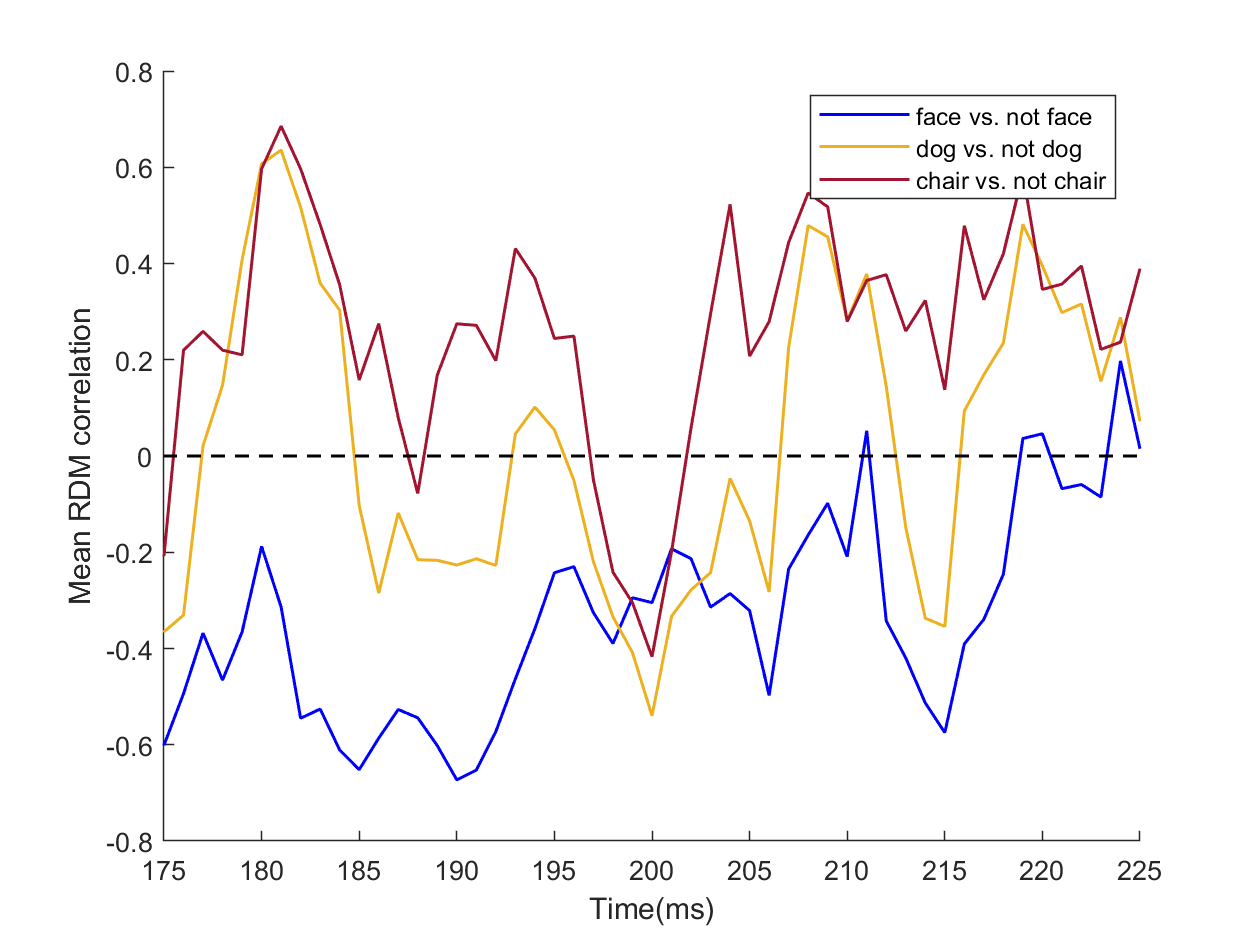

figure;
hold on
plot_face = zeros(1,225);
plot_dog = zeros(1,225);
plot_chair = zeros(1,225);
for i=175:225
    plot_face(i) = face_vs(i-174);
    plot_dog(i) = dog_vs(i-174);
    plot_chair(i) = chair_vs(i-174);
end
plot(plot_face,'Color','b','LineWidth',1.0);
plot(plot_dog,'Color','#EDB120','LineWidth',1.0);
plot(plot_chair,'Color','#A2142F','LineWidth',1.0);
plot(zeros(1,225),'Color','k','LineStyle','--','LineWidth',1.0);
legend('face vs. not face','dog vs. not dog','chair vs. not chair')
ylim([-0.8 0.8]);
xlim([175 225]);
xlabel("Time(ms)");
ylabel('Mean RDM correlation');
hold off

**Questions:**

**(a) **yes at first glance. it appears that at 200ms* "mean RDM correlation" *of face vs. others, dog vs. others and chair vs. others is the lowest. 

in other words, at 200 ms, the activation pattern of these 3 type of stimuli seem to be differentiable. but according to the Spearman test below,

at 200 ms, these categories are not differentiable. face and chair can be differentiated statistically from each other. but,  it seems that there is

statistically significant correaltion between dog and others (i.e. dog & face, dog & chair). So the final answer is No.

% time = 26 in this array equals -> time = 200 in the original dataset
rsa_face_200 = mean(transpose(squeeze(face_event_3D(:,26,:))));
rsa_dog_200 = mean(transpose(squeeze(dog_event_3D(:,26,:))));
rsa_chair_200 = mean(transpose(squeeze(chair_event_3D(:,26,:))));
[RHO1,PVAL1] = corr(rsa_face_200',rsa_dog_200','Type','Spearman');
[RHO2,PVAL2] = corr(rsa_face_200',rsa_chair_200','Type','Spearman');
[RHO3,PVAL3] = corr(rsa_chair_200',rsa_dog_200','Type','Spearman');
fprintf('face vs. dog => corr: %f , p-value: %f', RHO1,PVAL1);

face vs. dog => corr: -0.394368 , p-value: 0.001368

fprintf('face vs. chair => corr: %f , p-value: %f', RHO2,PVAL2);

face vs. chair => corr: -0.061767 , p-value: 0.626976

fprintf('chair vs. dog => corr: %f , p-value: %f', RHO3,PVAL3);

chair vs. dog => corr: -0.299267 , p-value: 0.016606